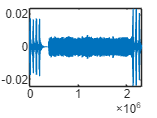

a_est = 6.5235e-04

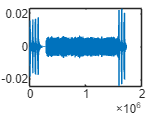

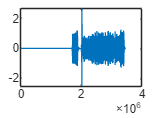

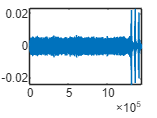

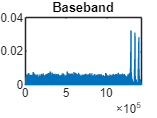

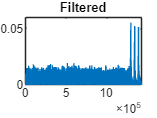

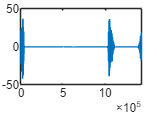

delay_os = 4800

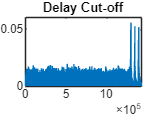

%%% Step 0 Load the .mat files and given values
load("test_rece_data_173048_1472.mat");
load("pilot_signal_for_synchronization.mat");
load("ofdm_map.mat");
load("benchmark_parameter_174623_1472.mat");
load("benchmark_rece_data_174623_1472.mat");
load("benchmark_Zw_174623_1472.mat");
load("itc_1007_compfilter.mat");
K = 2048; % Subcarriers
L = 200; % Taps
Fc = 24000; % Carrier Freq.
%B = 8000; % Bandwidth
W = 21; % # of ZP-OFDM symbols in 1 packet
Lambda = 24; % Oversampling Factor
Sr = 256000; % Sampling rate
%vel = 1.03;
%c = 1500;
%a_max = vel/c; % max Mach number (Doppler rate)

%%% Step 1: PB filter to remove noise beyond PB
y_in = rece_data_ofdm_test;
y_pb = bandpass(y_in, [-4000+Fc, 4000+Fc], Sr);
%plot(y_pb); % a_est is first tailend chirp peak - first chirp peak

%%% Step 2: Estimate Doppler rate (a_est)
T_tx = 8269.52; %In ms
T_txs = T_tx / 1000; %In sec
sr = 1 / Sampler; %Sampling rate in seconds
T_rx_est = 2115617 * sr; %Estimated Trx duration in sec 2117460 
a_est = (T_txs/T_rx_est)-1 % The minus 1 was missing before
%a_est = a_est_174623;%TA's a_hat value,benchmark_parameter_174623_1472.mat

%%% Step 3: Resampling w/ Doppler rate
y_pb_re = resample(y_pb, round((1+a_est)*1e5), 1e5);

%%% Step 4: Resampling from rx=256k to tx=192k Hz
Ls = 192;
Ms = 256;
Lp = 24;
N = Lp*Ls-1;
h = Ls*fir1(N, 1/Ms, kaiser(N+1, 7.8562));
Ytilda_pb_re = upfirdn(y_pb_re, h, Ls, Ms);
%plot(Ytilda_pb_re);
%freqz(Ytilda_pb_re, 1);

%%% Step 5: Synchronization
pilot = OFDM_data_pre_old; %load pilot_signal_for_syncronizaation.mat
%plot(pilot);

correlate = xcorr(Ytilda_pb_re, pilot); % Correlation with pilot signal
% plot(correlate); % Should see an obvious peak at 1st OFDM block

i = max(correlate); % Finds max value index for n_0
for j = 1:length(correlate)
    if i == correlate(j)
        n_0 = j - length(Ytilda_pb_re);
    end
end

Ytilda_n0 = Ytilda_pb_re(n_0:end); % Truncates signal to start at n_0
%plot(Ytilda_n0)

%%% Step 6 Convolution for PB -> BB
Ytilda_conv = conv(Ytilda_n0, h_comp); % Convolution with 101 sample vector
%plot(Ytilda_conv)
Ytilda_no_delay = Ytilda_conv(51:end); % Cut out first 50 data points delay

%%% Step 7 PB -> BB, Preallocate arrays in for loops
Fs = 192000;
Y_BB_I = zeros(1, length(Ytilda_no_delay)); 
Y_BB_Q = zeros(1, length(Ytilda_no_delay));
Y_BB = zeros(1, length(Ytilda_no_delay));
for n = 1:length(Ytilda_no_delay)   % As seen in handout
Y_BB_I(n) = Ytilda_no_delay(n)*2*cos(2*pi*Fc*n*1/Fs);
Y_BB_Q(n) = -Ytilda_no_delay(n)*2*sin(2*pi*Fc*n*1/Fs);
Y_BB(n) = Y_BB_I(n) + 1i*Y_BB_Q(n);
end
%plot(Y_BB)

%%% Step 8 Raised Cosine Convolution
beta = .125; % roll-off factor
Fs = 192000; % sampling frequency
Fd = 8000; % data/transfer rate
% lamda_oversamp = Fs/Fd; % lambda = 24 defined above works too
delay = 100;    % Given delay in part 1 before oversampling
span = 2*delay;
Rn = rcosdesign(beta, span, Fs/Fd, 'sqrt');%rcosine filter, similar to sinc
%plot(Rn)
%plot(abs(Y_BB));    % Checking signal before filtering
%title("Baseband");
Y_BB_filtered = conv(Y_BB, Rn); % Same as part 1 Step 5
%plot(abs(Y_BB_filtered))    % Checking signal after filtering
%title("Filtered");
%plot(real(fft(Y_BB)))
delay_os = length(Y_BB_filtered)-length(Y_BB);   % Upsampled delay
Y_BB_no_delay=Y_BB_filtered(delay_os/2+1:length(Y_BB_filtered)-delay_os/2);
%plot(abs(Y_BB_no_delay));   % Should be the same length as Y_BB
%title("Delay Cut-off");


%%% Step 9 Grid Search
% Preallocation of scalars, array, and matrices
Ts = 1/Fs; % Sample Period
zp_up = (K+L)*Lambda; %Zero padding sizes for up/down sampled
zp_down = K+L;
i = 1:zp_down; %Column and row vectors for fft matrix
m = transpose(1:2248);
fft_matrix = exp((-1i*2*pi*(m-1)*(i-1))/K); % FFT
l_eps = 41; % length epsilon [-2:.1:2]
l_n0 = 201; % length starting index [2200:1:2400]
P = l_eps*l_n0; %eps*n0 length 
ds_idx = (0:Lambda:zp_down*Lambda-1); % down sample index
ds_idx2 = ds_idx.*ones(l_eps, length(ds_idx)); % Applies all epsilons to n
% Preallocation of n = 0,1,...zp_down for all eps
n_idx = zeros(P, length(ds_idx2)); % n = 0,1,...zp_down for all eps
comb_eps_nidx = zeros(P, length(ds_idx2)); % n_idx*eps

% Compensation loops and matrices
for comb_eps_n0 = l_eps:l_eps:P % Combining all n, n0 for next eps loop
    eps_idx = comb_eps_n0-(l_eps-1):comb_eps_n0; % 41 rows
    n_idx(eps_idx, :) = comb_eps_n0+2199+ds_idx2; % n+n0
end
Y_BB_ds = Y_BB_no_delay(n_idx); % Downsampling matrix
for eps = 1:1:41 % Allocates eps to all n, n0 values in n_idx
    comb_eps_nidx(eps:l_eps:P, :) = (eps*.1-2.1)*n_idx(eps:l_eps:P, :);
end
CFO_ds = Y_BB_ds.*exp(-2i*pi*Ts*comb_eps_nidx); % CFO comp./d.s. combined
Z_1_all = fft_matrix*transpose(CFO_ds); % Generate frequency data

% Retrieve null carriers and set them to 1
min_OFDM = zeros(zp_down, 1);
for k = 1:K
    if ofdm_map(k, 1) == 0
        min_OFDM(k, 1) = 1;
    end
end

% Sum power of null subcarriers and find the minimum
P_NULL = sum(Z_1_all.*conj(Z_1_all).*min_OFDM);
pnmin = find(P_NULL == min(P_NULL));

% Set n0 and eps based on minimum found
n_0_1 = floor(pnmin/41) + 2200;
eps_1 = mod(pnmin, 41)*0.1-2.1;

% Repeat previous steps w/ new n0/eps to generate best frequency data
n_idx_1 = n_0_1+ds_idx;
CFO_ds_1 = Y_BB_no_delay(n_idx_1).*exp(-2i*pi*eps_1*Ts*n_idx_1);
Z_1= fft_matrix*transpose(CFO_ds_1);

% Store values for following OFDM blocks
Z_all = zeros(zp_down, W);
Z_all(1:end, 1) = Z_1;

n_all = zeros(W, 1);
n_all(1, 1) = n_0_1;

eps_all = zeros(W, 1);
eps_all(1, 1) = eps_1;

%%% Step 10
% Preallocation
n_0_w_1 = n_0_1; % Launch point for finding n0 value of next OFDM block 
l_n0w = 4*Lambda+1; % length starting index [-2Lambda:1:2Lambda]
P = l_eps*l_n0w; %eps*n0w length
n_idx = zeros(P, length(ds_idx2)); % n = 0,1,...zp_down for all eps
comb_eps_nidx = zeros(P, length(ds_idx2)); % n_idx*eps

for w = 2:W % Loop for remaining OFDM blocks

    % Compensation steps w/ new n0 range
    for comb_eps_n0 = l_eps:l_eps:P
        eps_idx = comb_eps_n0-(l_eps-1):comb_eps_n0; % 41 rows
        Lambda_idx = comb_eps_n0/l_eps-1-2*Lambda; % Current Lambda value
        n_idx(eps_idx, :) = n_0_w_1+zp_up+Lambda_idx+ds_idx2;% n+n0w
    end
    % The rest of the compensation steps are the same as the first block
    % Read lines 122-148 comments
    Y_BB_ds = Y_BB_no_delay(n_idx); 
    for eps = 1:1:41
        comb_eps_nidx(eps:l_eps:P, :) = (eps*.1-2.1)*n_idx(eps:l_eps:P, :);
    end
    CFO_ds = Y_BB_ds.*exp(-2i*pi*Ts*comb_eps_nidx);
    Z_w_all = fft_matrix*transpose(CFO_ds);

    P_NULL = sum(Z_w_all.*conj(Z_w_all).*min_OFDM);
    pnwmin = find(P_NULL == min(P_NULL));

    n_0_w = n_0_w_1+zp_up+floor(pnwmin/41)-2*Lambda;
    eps_w = mod(pnwmin, 41)*0.1-2.1;

    n_idx_w = n_0_w+ds_idx;
    CFO_ds_w = Y_BB_no_delay(n_idx_w).*exp(-2i*pi*eps_w*Ts*n_idx_w);
    Z_w= fft_matrix*transpose(CFO_ds_w);

    Z_all(1:end, w) = Z_w;
    n_all(w, 1) = n_0_w;
    eps_all(w, 1) = eps_w;
    n_0_w_1 = n_0_w; % Itterates previous n0w to current n0w
end
